# Prepare Data for Regression

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the color correction dataset.

load ../data/ColorCast/trainingData.mat

The dataset was created from photos such as `dog.jpg`. Load and display this unprocessed image.

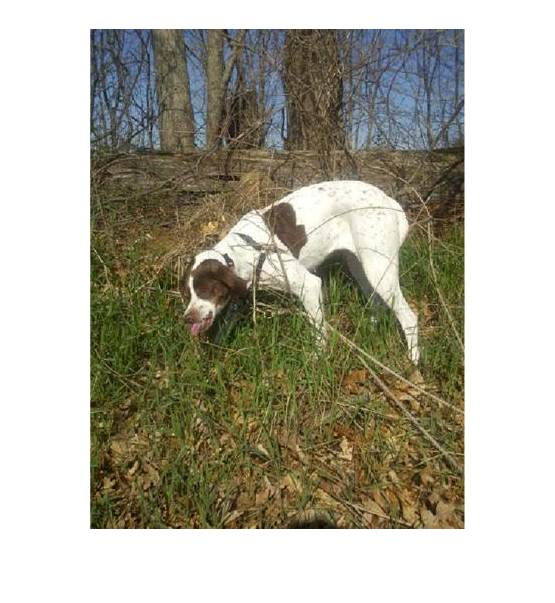

img = imread("../data/dog.jpg");
imshow(img)

## Task 1

The training data for a regression problem can be stored in a variety of formats. For this example, you will work with a table named `trainingData`.

The first variable of the table is a list of filenames. These filenames correspond to the training images.

To view these images, you need to first extract this data from the table. You can access elements of a table using dot notation and array indexing.

`tableName.VariableName`

trainfiles = trainingData.File;

## Task 2

Recall that you can use curly braces (`{}`) to extract the data from cell array.

fn = trainfiles{1}

fn = '../data/ColorCast/TrainingImages/img0001.jpg'

## Task 3

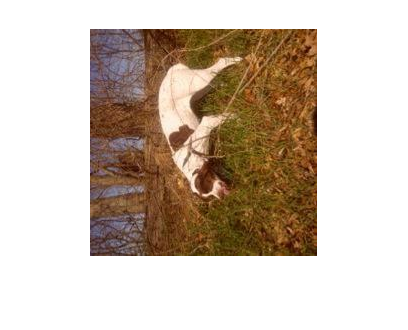

im = imread(fn);
imshow(im)

## Task 4

The displayed image shows one of the training images. Before training a network on any data set, it is a good idea to investigate many images to confirm that the images look as expected.

Although you could loop through multiple images, it is efficient to create a single montage.

Creating a datastore of some images will make them easier to view.

imds = imageDatastore(trainfiles(1:9));

## Task 5

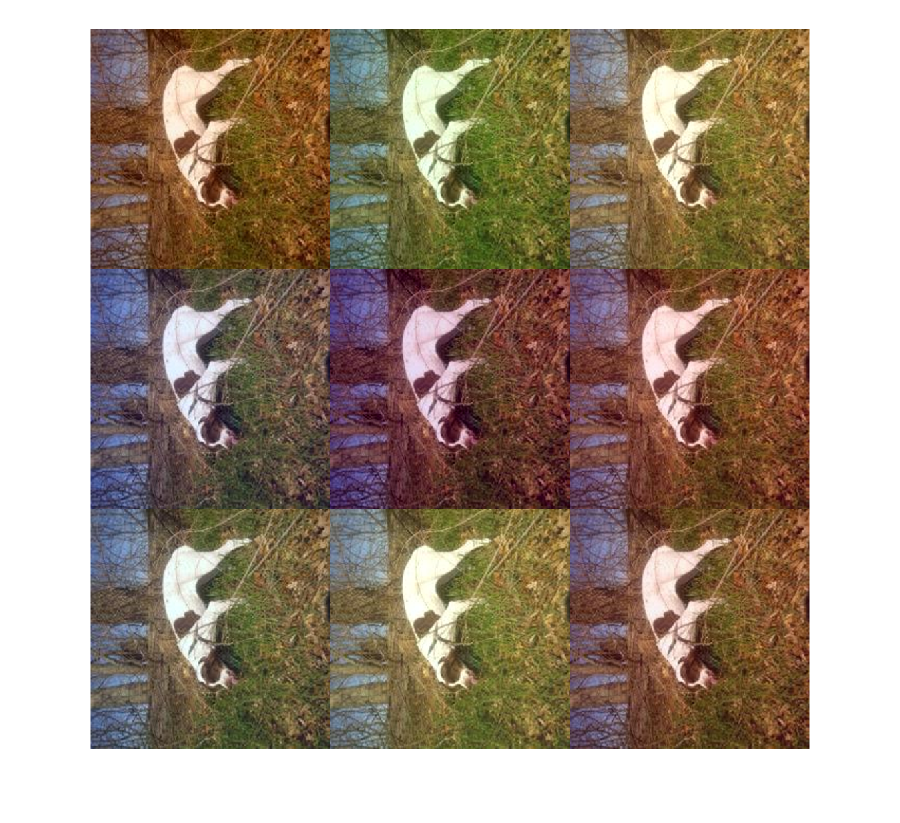

montage(imds)

## Task 6

The second variable of the table contains a three element vector for every image. This vector is the *response* for the corresponding image.

To view the filenames with their corresponding response values, you can extract a portion of the table using regular array indexing.

`tableName``(``rows``,``cols``)`

subsetData = trainingData(1:9, :)

subsetData = 9×2 table
                          File                               Color      
    ________________________________________________    ________________

    {'../data/ColorCast/TrainingImages/img0001.jpg'}    18    -15    -25
    {'../data/ColorCast/TrainingImages/img0002.jpg'}     5     16     -8
    {'../data/ColorCast/TrainingImages/img0003.jpg'}    32     15     -1
    {'../data/ColorCast/TrainingImages/img0004.jpg'}    -7    -13     14
    {'../data/ColorCast/TrainingImages/img0005.jpg'}    -3    -40     -8
    {'../data/ColorCast/TrainingImages/img0006.jpg'}    20    -22    -11
    {'../data/ColorCast/TrainingImages/img0007.jpg'}     3      2      8
    {'../data/ColorCast/TrainingImages/img0008.jpg'}    26     22      7
    {'../data/ColorCast/TrainingImages/img0009.jpg'}    15    -15     -9


## Task 7

The three element vector in `Color` corresponds to the red, green, and blue added to the image. Notice that the first displayed image has a red tint, and the color added was primarily red.

If your images are properly sized, then you can use the `trainingData` table to train your network. If they need to be resized, you can create an augmented image datastore using `trainingData`.

`auds` `=` `augmentedImageDatastore``([``r` `c``]``,``tbl``)`

trainds = augmentedImageDatastore([224 224], trainingData);